# Antenna and Free-Space Propagation In-Class Exercises

These exercises follow the lectures and are to be done at the end of each section.

## Problem 1:  Computing Wavelength and E-Field Amplitude

Suppose that an EM-plane wave has:

- Power flux density is 1 nW/m^2

- Freq = 2.3 GHz

Print the:

- Maximum E-field value assuming a characteristic impedance of eta = `120*pi` ohms

- Wavelength.  You may use the `physconst('Lightspeed')` command to get the speed of light.

Make sure you print the units.

% TODO
eta = 120*pi;
freq = 2.3e9;
pflux = 1e-9;
E0 = sqrt(2*pflux*eta);

lambda = physconst('LightSpeed')/freq;

## Problem 2:  Computing Power in a LTE PSS

In an LTE system, each base station (called eNB in 3GPP terminology) periodically transmits a Primary Synchronization Signal (PSS) so that mobiles  (called a UEs or user equipments) can detect the base station.  The PSS occupies:

- In frequency:  72 sub-carriers at 15 kHz per sub-carrier

- In time:  One OFDM symbol = 2048 samples at 30.72 Ms/s

The following diagram shows the transmission of the PSS when it is configured to be transmitted every 5ms.  Other synchronization and reference signals are also shown.

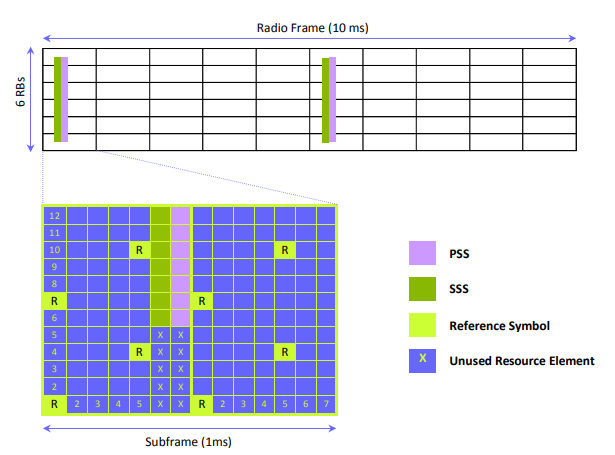

Suppose the eNB has a total transmit power of 43 dBm uniformly over 20 MHz.  The path loss between the eNB and UE is 100 dB.  What is the received energy per PSS?  Print your answer in dBmJ.

% TODO
Ptx = 43; % transmit power in dBm
PL = 100;
bwPss = 72*15e3;  % bandwidth of the PSS in Hz
RxPss_dBm = Ptx - PL + 10*log10(bwPss/(20*1e6)); % dBm
symbol_dur = 2048/(30.72e6);
E_dBmJ = RxPss_dBm + 10*log10(symbol_dur);

## Problem 3:  Creating and Displaying a Patch Antenna

Create the 28 GHz patch antenna as follows:

% Compute the wavelength
fc = 28e9;
c=physconst('Lightspeed');
lambda = c/fc;

% Create the patch antenna
len = 0.49*lambda;
groundPlaneLen = lambda;
ant = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);

Use the `ant.show()` command to display the antenna.

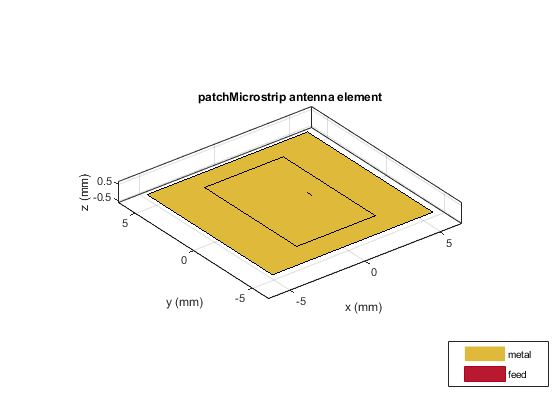

% TODO
ant.show();

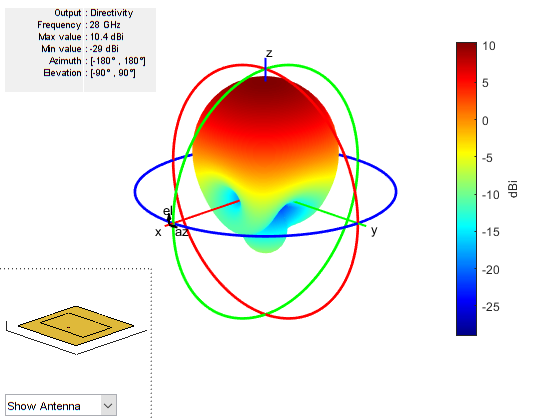

ant.pattern(fc);

Now suppose the TX is at the origin and we have a RX target at the following position:

rxPos = [1000,500,100];

Find the azimuth and elevation angle and distance to the RX.  Use the `car2sph` and `rad2deg` commands:

% TODO
[TH,PHI,R] = cart2sph(rxPos(1),rxPos(2),rxPos(3));
az0 = rad2deg(TH);
el0 = rad2deg(PHI);
rad0 = R;

Now rotate the antenna to point towards the target.  You can do this with the code:

where y`Rot` and `zRot` are the angles to rotate the element in the y and z axes.  Select `yRot` and `zRot, run the` command to point to the target and display the antenna.  You may want to use the `view([...])` command to select a good view point so you can see the front of the antenna.

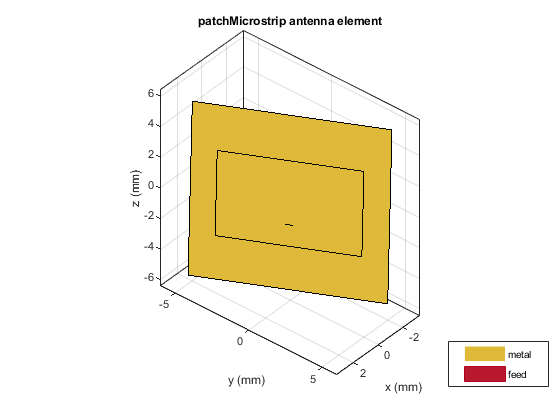

% TODO
yRot = 90-el0;
zRot = az0;
ant.set('Tilt', [yRot, zRot], 'TiltAxis', [0 1 0; 0 0 1]);
show(ant);
view(130,37);

## Problem 4:  Plotting the Far Field Radiation Pattern

Use the `ant.pattern` command to get the pattern of the rotated antenna from the previous part.

% TODO:
[dir, az, el] = ant.pattern(fc, 'Type',"directivity");

Use the `imagesc` command to plot the antenna pattern as a function of the azimuth and elevation angles.  Add a colorbar, label the axes.  Place a marker at the location `[az0, el0],` the desired direction. 

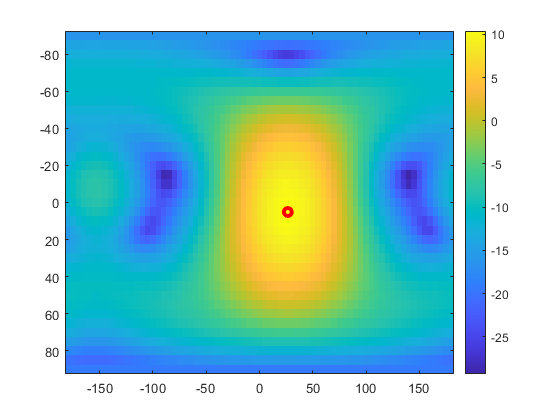

% TODO
imagesc(az,el,dir);
hold on;
plot(az0,el0,'ro', "LineWidth",3);
colorbar;

Use the `griddedInterpolant` object with the directivity data.  Then use the gridded interpolant to find the directivity to the target at `[az0, el0]`.

% TODO
F = griddedInterpolant({el,az},dir);
dir0 = F(el0, az0);

Compute the free space path loss including the TX directivity to the target.

% TODO  
lambda = physconst('LightSpeed')/fc;
plOmni = fspl(rad0, lambda)

plOmni = 122.3946

plDir = plOmni - dir0

plDir = 112.0260